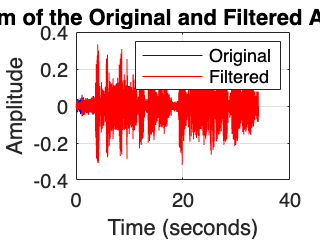



% Load the audio file
[y, Fs] = audioread('you belong with me noisy.mp4');

% Check if the audio is stereo (2 columns)
if size(y, 2) == 2
    y = mean(y, 2);  % Convert stereo to mono
end

% Define the duration of the noise segment
noise_duration = 1;  % 1 second
noise_samples = noise_duration * Fs;  % Number of samples in 1 second

% Extract the noise segment
noise = y(1:noise_samples); % Extract first second as noise reference
noise = repmat(noise, ceil(length(y)/length(noise)), 1);  % Repeat to match y length
noise = noise(1:length(y)); % Trim to exact size of y
noise = noise(:);  % Ensure it's a column vector
y = y(:);
lms = dsp.LMSFilter('Length', 32, 'StepSize', 0.01);
[filtered_signal, err] = lms(noise,y);
t = (0:length(y)-1) / Fs;
figure(1);
plot(t, y, 'b');
hold on;
plot(t, err, 'r');
xlabel('Time (seconds)');  
ylabel('Amplitude');  
title('Waveform of the Original and Filtered Audio Signals');  
grid on;
legend('Original', 'Filtered');